检测到基频: 95.21 Hz
THD: 0.0473 (4.73%)
峭度: 25.4848
最大滑动峭度: 3.9278

频段能量分布:
  [0-200 Hz]: 40.93%
  [200-500 Hz]: 4.45%
  [500-1000 Hz]: 6.17%

========== 综合评估 ==========
非线性综合评分: 0.464
评估等级: 弱非线性
控制策略建议: 建议启用混合控制，混合系数 α 在 0.6~0.8


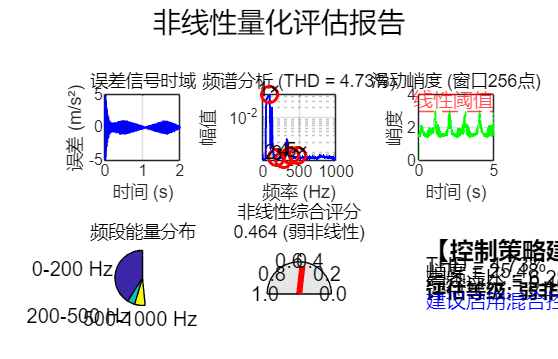


报告已保存至 nonlinear_metrics.mat


 fs = 10000;
 t = (0:5*fs-1)'/fs;
 % 线性信号（50Hz正弦波）
 linear_signal = 0.5 * sin(2*pi*50*t);
 % 非线性信号（添加谐波和冲击）
 nonlinear_signal = linear_signal + 0.1*sin(2*pi*150*t) + 0.05*sin(2*pi*250*t);
 nonlinear_signal(1:100:end) = nonlinear_signal(1:100:end) + 0.2;  % 模拟冲击
 
 load('simulation_results.mat');  % 加载您的仿真结果
 metrics = nonlinear_quantification(error_signal, fs);

检测到基频: 48.83 Hz
THD: 0.0344 (3.44%)
峭度: 1.1812
最大滑动峭度: 1.3685

频段能量分布:
  [0-200 Hz]: 68.53%
  [200-500 Hz]: 8.19%
  [500-1000 Hz]: 3.35%

========== 综合评估 ==========
非线性综合评分: 0.054
评估等级: 线性
控制策略建议: FxLMS 主导控制，无需神经网络补偿


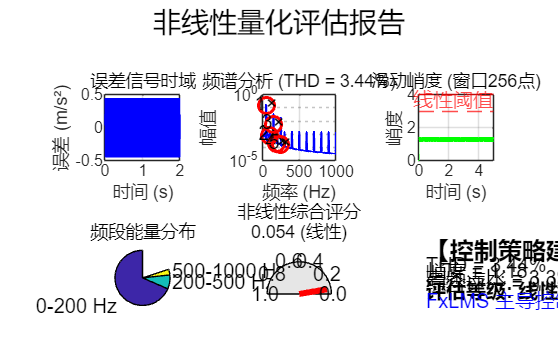


报告已保存至 nonlinear_metrics.mat



 
 metrics = nonlinear_quantification(nonlinear_signal, fs);